# MATLAB WorkShop



clear; clc; close all;

## Q1:

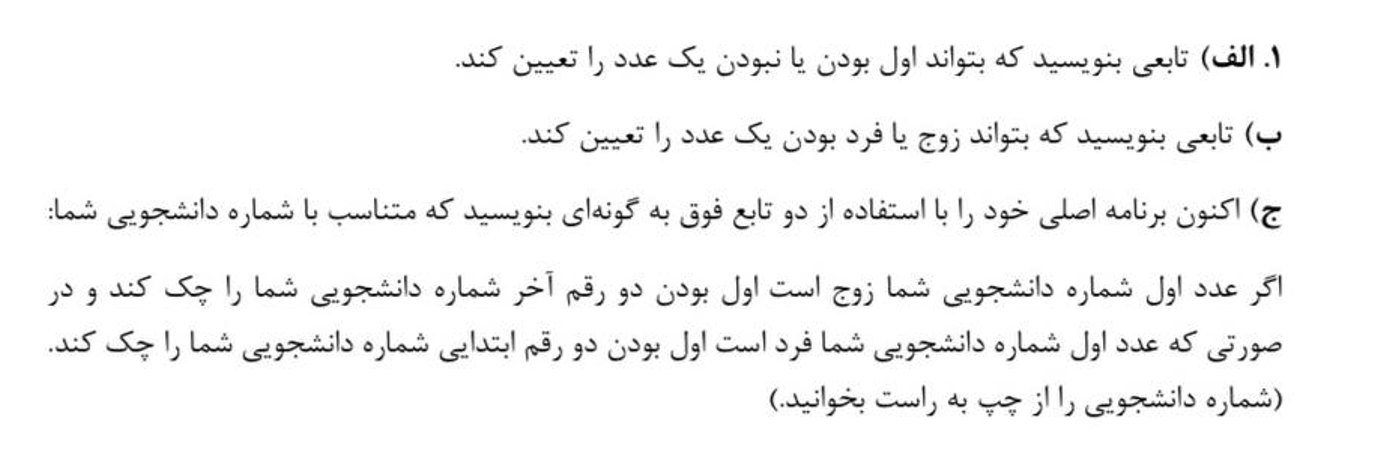

### Part 1) 

To check whether a Number is Prime or not, we need to check from 2 to N/2 and determine the remainder of the division of N and these numbers. if any of these remainders gets equal to 0, then this number is not prime!

Below, we have some examples of prime numbers checked using this function named is_prime_Mine:



M = [47 , 137 , 221, 155];
for i=1:length(M)
    is_prime_Mine(M(i));
end

This Number is prime
This Number is prime
This Number is NOT!! prime --> (13*17)
This Number is NOT!! prime --> (5*31)


### Part 2)

Being even, means to have zero remainder when dividing this number, N, to base number 2. if the number is not Even then it is Odd!

Test = [1, 0 , 22, 31, 121, 248];
for i=1:length(Test)
    is_odd_Mine(Test(i));
end

This number is Odd!
This number is Even!
This number is Even!
This number is Odd!
This number is Odd!
This number is Even!


STUD_Num = 810111453 ;
Temp   = STUD_Num;
STUD_Num_vec =[];
cntr = 0;

while(1)
  cntr = cntr+1;
  Temp_2 = floor(Temp/10);
  Rem =  Temp - 10*Temp_2 ;
  STUD_Num_vec(cntr) = Rem;
  Temp = Temp_2;
  if(Temp==0)
      STUD_Num_vec = flip(STUD_Num_vec);
      break;
  end

end


if(is_odd_Mine(STUD_Num_vec(1)))
    % It is Even
   is_prime_Mine(STUD_Num_vec(end) + 10*STUD_Num_vec(end-1)  ); % CHecking to see if Last 2 Digits are prime
        

else
    %it is Odd
    is_prime_Mine(10*STUD_Num_vec(1) + STUD_Num_vec(2)  );

end

This number is Even!


This Number is prime=>53


## Q2:


Num_of_Dim = sum(STUD_Num_vec);

p =9;

x  = min(STUD_Num_vec(1),STUD_Num_vec(end)) + abs(STUD_Num_vec(end)-STUD_Num_vec(1))*rand(1,Num_of_Dim);

NORM = normp_mine(x,p)

NORM = 9.9678

function flag = is_prime_Mine(n)

flag=1;

for i=2:floor(n/2)+1

    if(mod(n,i)==0)
        flag= 0;
        N = i;
         break;
    end
end


if(flag==1)
    disp("This Number is prime=>"+n)

else
    disp("This Number is NOT!! prime --> ("+N+"*"+n/N+")")
end


end


function flag = is_odd_Mine(n)

if(mod(n,2)==0)
    disp("This number is Even!")
    flag=1;
else
    disp("This number is Odd!")
    flag=0;
end



end


function  NORM = normp_mine(x,p)

NORM = (sum(x.^p))^(1/p) ;


end
